# plant model: double integrator


$$\ddot{x} = u$$


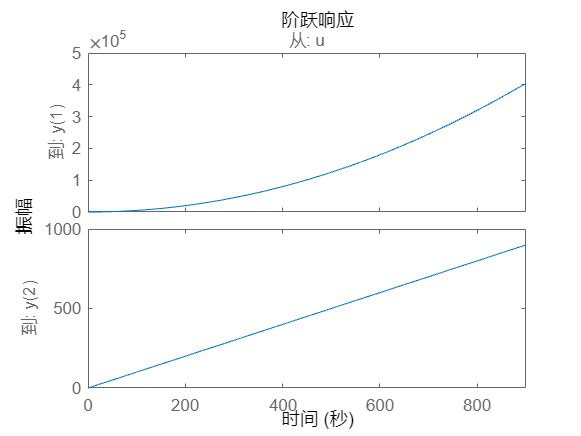

A = [0 1; 0 0];
B = [0; 1];
C = [1 0; 0 1];
D = 0;
plant = ss(A, B, C, D);
plant.InputName = 'u';
plant.OutputName = 'y';
plant.StateName = {'x1', 'x2'};
step(plant);

# controller

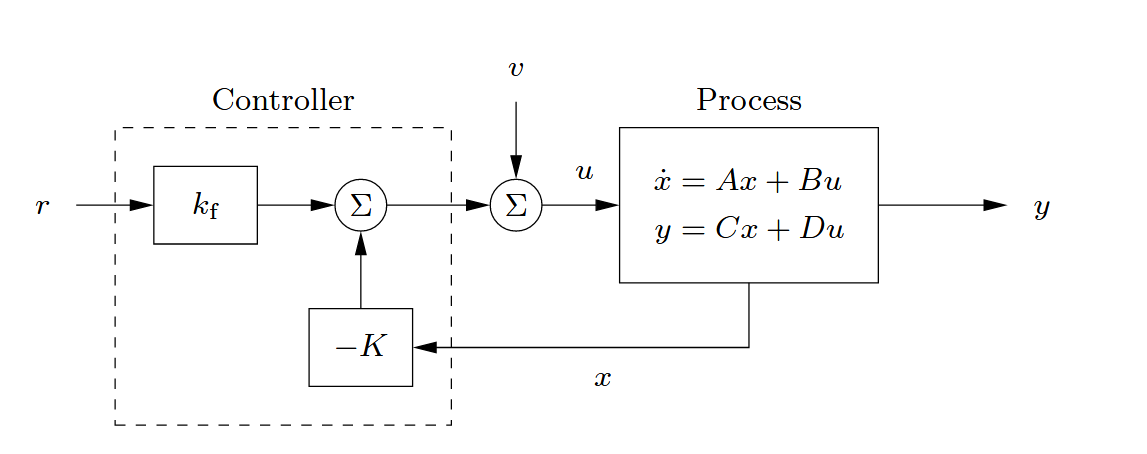

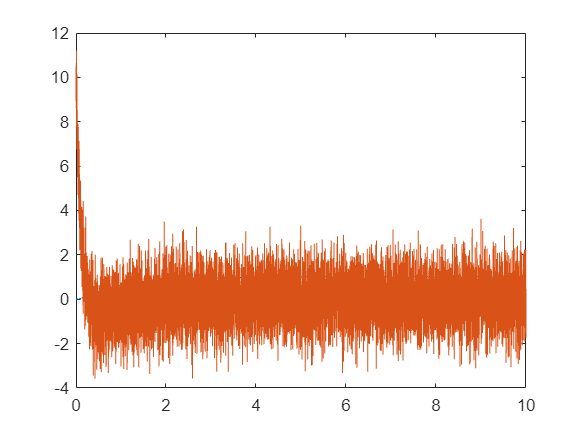

K = [10,10];
kf = -1 / (C(1,:) * ((A - B * K) \ B));
Kgain = tf(K);
kfgain = tf(kf);
kfgain.u = 'r';
kfgain.y = 'kfr';
Kgain.u = 'y';
Kgain.y = 'Kx';
add1 = sumblk('e = kfr - Kx');
add2 = sumblk('u = e + v');
sys = connect(kfgain, add1, Kgain, add2, plant, {'r', 'v'}, {'y(1)', 'u'});
N = 10000;
t = linspace(0, 10, N);
r = ones(N, 1);
v = 1 * randn(N, 1);
y = lsim(sys, [r, v], t);
plot(t, y);